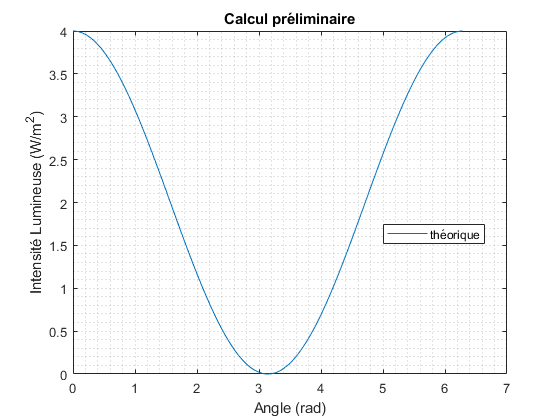

clear all;close all;

% THEORIQUE
dphi = linspace(0,2*pi,360);
I1 = 1;I2 = 1;

Vs = I1+I2+2*sqrt(I1*I2)*cos(dphi);

plot(dphi,Vs)
xlabel('Angle (rad)')
ylabel('Intensité Lumineuse (W/m^2)')
title('Calcul préliminaire')
legend('théorique','location','best')
grid on

Si on veut pas déformer un signal -> Fonction linéaire

## PARTIE 2

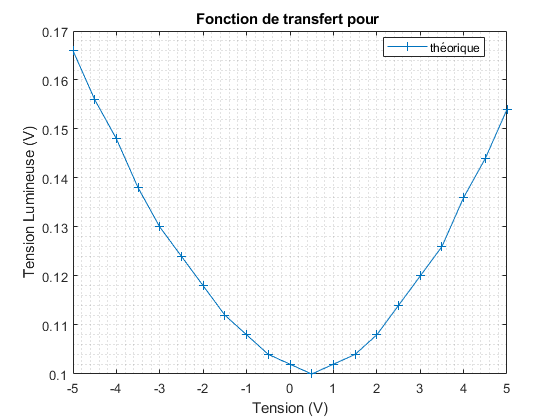

% PRATIQUE
V = -5:0.5:5;
Vs = [166 156 148 138 130 124 118 112 108 104 102 100 102 104 108 114 120 126 136 144 154]*1e-3;
figure
plot(V,Vs,'+-')
xlabel('Tension (V)')
ylabel('Tension Lumineuse (V)')
title('Fonction de transfert pour ')
legend('théorique','location','best')
grid on

On peut pas calculer $V_{\pi }$ car on n'a pas pas deux valeurs max. La courbe obtenue a partir des valeurs pratiques est similaire à celle théorique, mais l'on a un léger offset (valeur min n'est pas à V=0).

## PARTIE 3

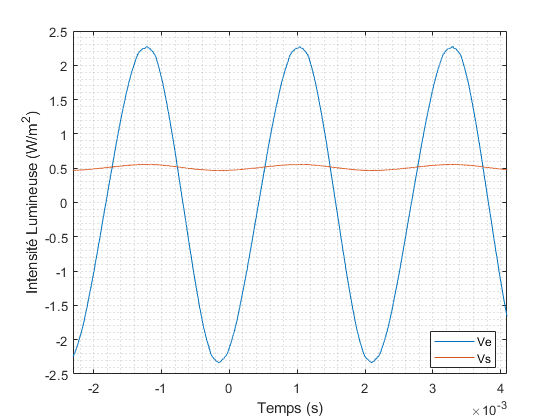

load ch11.dat
load ch21.dat
figure
figure
plot(ch21(:,1),ch21(:,2),ch11(:,1),ch11(:,2)*4)
title("")
ylabel('Intensité Lumineuse (W/m^2)')
xlabel("Temps (s)")
xlim([min(ch21(:,1)) max(ch21(:,1))])
legend("Ve","Vs","Location","best")
grid minor

Dans le cas où l'on est dans la zone linéaire (3.5V dans notre cas) et Ve d'amplitude faible, alors on a une transmission parfaite.

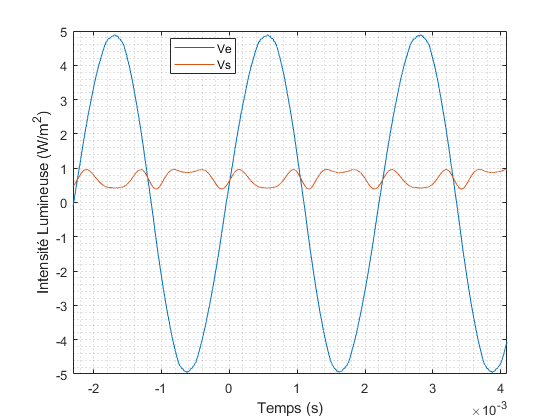

load ch12.dat
load ch22.dat
figure
plot(ch22(:,1),ch22(:,2),ch12(:,1),ch12(:,2)*4)
title("")
ylabel('Intensité Lumineuse (W/m^2)')
xlabel("Temps (s)")
xlim([min(ch22(:,1)) max(ch22(:,1))])
legend("Ve","Vs","Location","best")
grid minor

Dans le cas où l'on est dans la zone linéaire et Ve a une amplitude élevée, alors la transmission est mauvaise. En effet, le signal est tellement ample qu'il se retrouve dans les zones non-linéaires (creux et pics), ce qui fait que la transmission est atténué, ou on peut voir une one de fréquence double apparaitre).

2) En zone non linéaire (sommet ou creux), augmenter l'amplitude accentue la déformation du signal.

Pour transmettre le signal le plus fidèlement, il faut une amplitude faible.

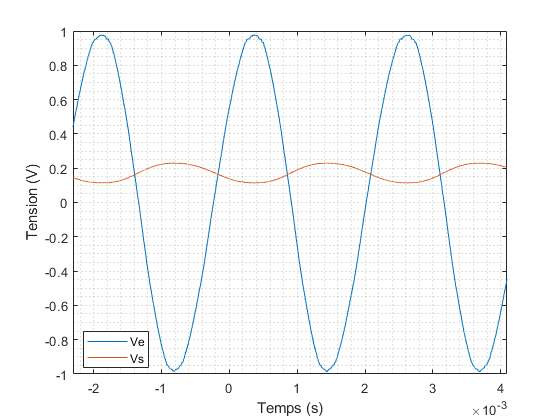

load ch13.dat
load ch23.dat
figure
plot(ch23(:,1),ch23(:,2),ch13(:,1),ch13(:,2))
title("")
ylabel("Tension (V)")
xlabel("Temps (s)")
xlim([min(ch23(:,1)) max(ch23(:,1))])
legend("Ve","Vs","Location","best")
grid minor

La phase n'a aucune importance dans la perception du signal. Un signal déplasé de pi/2 sera entendu de la même manière qu'un signal non déphasé.

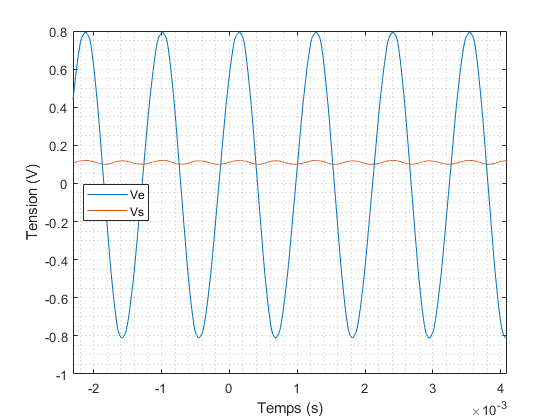

load ch14.dat
load ch24.dat
figure
plot(ch24(:,1),ch24(:,2),ch14(:,1),ch14(:,2))
title("")
ylabel("Tension (V)")
xlabel("Temps (s)")
xlim([min(ch24(:,1)) max(ch24(:,1))])
legend("Ve","Vs","Location","best")
grid minor

Lorsque l'on double la fréquence Ve, on quadruple la fréquence de Vs. C'est à dire que augmenter d'une octave Ve fera que l'on augmenter de deux octaves Vs.

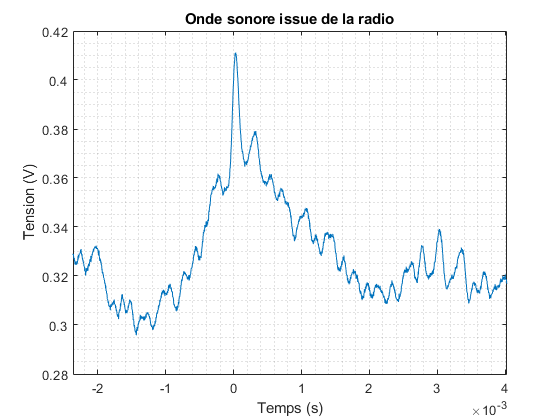

load ch1b.dat
plot(ch1b(:,1),ch1b(:,2))
xlim([min(ch1b(:,1)) max(ch1b(:,1))])
title("Onde sonore issue de la radio")
ylabel("Tension (V)")
xlabel("Temps (s)")
grid minor

Le signal de la radio est archaique, à l'inverse du signal précédent (monochromatique). Modifier la valeur de la tension DC modifiera la qualité ainsi que son niveau sonore.

Si l'on augmente trop le son de l'ordinateur, on entend du bruit. Augmenter le son équivaut à faire varier son amplitude, et tout comme le son monochromatique, une amplitude trop importante aura pour conséquence que certaines partie de Vs seront sur les zones non-linéaires.

# Q3.9

F=10Ghz et Power=13dBm

load WaveData20230323_000.csv
plot(WaveData20230323_000(:,1),log10(WaveData20230323_000(:,2)))

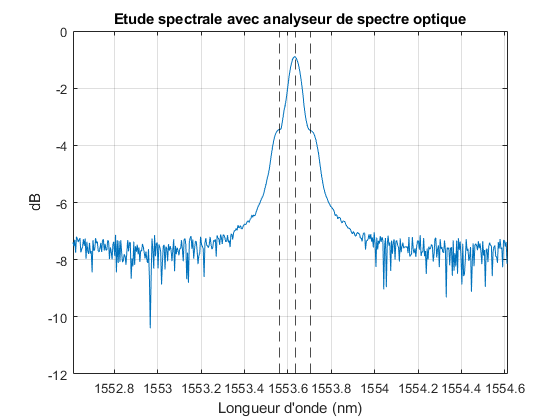

xline(1553.633,'k--');xline(1553.563,'k--');xline(1553.703,'k--');
xlim([min(WaveData20230323_000(:,1)) max(WaveData20230323_000(:,1))])
title("Etude spectrale avec analyseur de spectre optique")
ylabel("dB")
xlabel("Longueur d'onde (nm)")
grid on

10) Pour une transmission d'un signal 5GHz, nous ne voyons plus le signal car il n'est plus dans la résolution de l'analyseur de spectre (RBW etc).

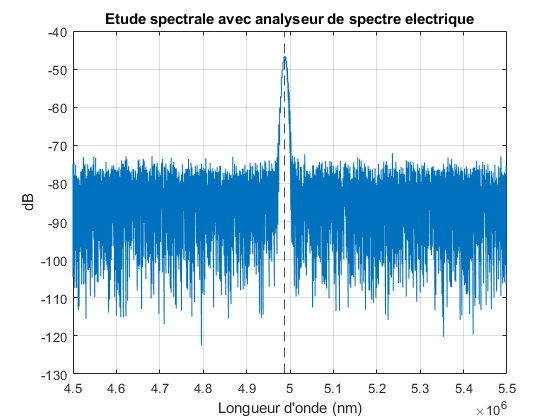

load final.dat
plot(final(:,1),final(:,2))
xline(4988000,'k--');
title("Etude spectrale avec analyseur de spectre electrique")
ylabel("dB")
xlabel("Longueur d'onde (nm)")
grid on